% SIMULATION USED FOR SHOWING COULOMB'S LAW

% Done in 4  hours offically finished on:
%   12/10/2024 @ 9:52 PM

% Issues that constanly came up:
% Fields were backwards, arrows were not showing
% Could not integrate E-Field Strength with unit vectors when suing quiver

% Solutions:
% Final - Inital fixed backwards fields, Arrows where given e-fields that
% were at the 10 ^ -12 so they were too small to see
% Realized that I could multiple the unit vectors with E-field Strength if
% the result was multipled by a factor of 10^9

tic

% Constants %
cou_cont = 8.9876e9 % N*m^2/C^2

cou_cont = 8.9876e+09

electron_q = -1.6021765e-19 % C

electron_q = -1.6022e-19

proton_q = 1.6021765e-19    % C

proton_q = 1.6022e-19


% Whole Coordinate Plane %
X = linspace(-6,10,30)

X =    -6.0000   -5.4483   -4.8966   -4.3448   -3.7931   -3.2414   -2.6897   -2.1379   -1.5862   -1.0345   -0.4828    0.0690    0.6207    1.1724    1.7241    2.2759    2.8276    3.3793    3.9310    4.4828    5.0345    5.5862    6.1379    6.6897    7.2414    7.7931    8.3448    8.8966    9.4483   10.0000


size_Plot = size(X,2)

size_Plot = 30

dist = 0;

% Electron Coords %
x_e = size(X,2)/2;
y_e = size(X,2)/2;

% Proton Coords %
x_p = size(X,2)/4;
y_p = size(X,2)/3;

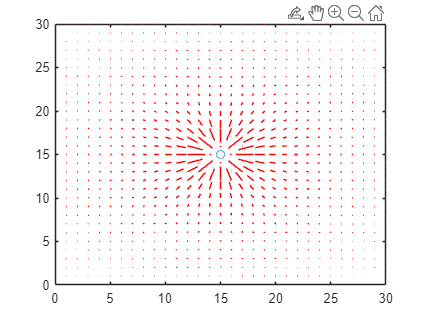

% ELECTRON FIGURE %

plot(x_e,y_e,'o')  % empty figure to be filled from for loop
hold on
for i = 1:size_Plot
    for j = 1:size_Plot
    % plot(i,j,'*')   % Testing if every point in graph is grabbed
    % quiver(i,j,1,2) % Testing features of quiver

    comp_X = i - x_e;
    comp_Y = j - y_e;

    r = r_dist( comp_X , comp_Y ); % Get distance between points for unit vectors
    
    e_force = Coulombs_force(electron_q,r,cou_cont)*10^10;

    if any(abs(e_force) > 2)    % Used to Keep arrows resonable
        e_force = e_force * 10^-2;
    end

    % Unit Vectors %
    U = (comp_X/r)*e_force;
    V = (comp_Y/r)*e_force;
    % plot(i,j,"*")     % For plotting points
    quiver(i,j,U,V,0,'r')


    end
end
hold off

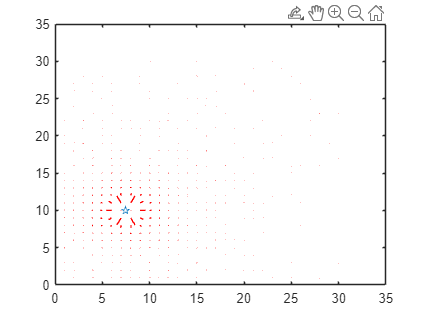

% PROTON FIGURE %

plot(x_p,y_p,"penta")  % empty figure to be filled from for loop
hold on
for i = 1:size_Plot
    for j = 1:size_Plot
    % plot(i,j,'*')   % Testing if every point in graph is grabbed
    % quiver(i,j,1,2) % Testing features of quiver

    comp_X = i - x_p;
    comp_Y = j - y_p;

    r = r_dist( comp_X , comp_Y ); % Get distance between points for unit vectors
    
    e_force = Coulombs_force(proton_q,r,cou_cont)*10^9;


    if any(abs(e_force) > 2)  
        e_force = e_force * 10^-2;
    end

    % Unit Vectors %
    U = (comp_X/r)*e_force;
    V = (comp_Y/r)*e_force;
    % plot(i,j,"*")     % For plotting points
    quiver(i,j,U,V,'r')


    end
end
hold off

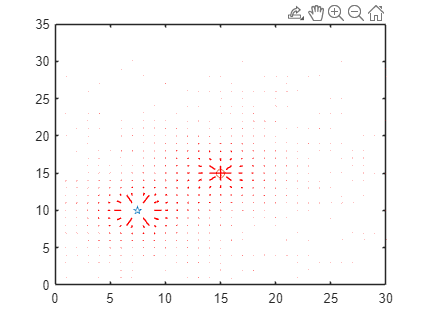

% Both in same graph %

plot(x_p,y_p,"penta")
hold on
plot(x_e,y_e,'o')

for i = 1:size_Plot
    for j = 1:size_Plot
    % plot(i,j,'*')   % Testing if every point in graph is grabbed
    % quiver(i,j,1,2) % Testing features of quiver

    comp_X_p = i - x_p;
    comp_Y_p = j - y_p;

    comp_X_e = i - x_e;
    comp_Y_e = j - y_e;

    r_p = r_dist( comp_X_p , comp_Y_p ); % Get distance between points for unit vectors
    r_e = r_dist( comp_X_e , comp_Y_e );

    e_force_p = Coulombs_force(proton_q,r_p,cou_cont) * 10^9;
    e_force_e = Coulombs_force(electron_q,r_e,cou_cont) * 10^9;
    
    if any(abs(e_force_p) > 2)  
        e_force_p = e_force * 10^-2;
    end

    if any(abs(e_force_e) > 2)  
        e_force_e = e_force * 10^-2;
    end

    Tot_X_comp = (comp_X_p/r_p)*(e_force_p) + (comp_X_e/r_e)*(e_force_e);
    Tot_Y_comp = (comp_Y_p/r_p)*(e_force_p) + (comp_Y_e/r_e)*(e_force_e);

    % Unit Vectors %
    U = (Tot_X_comp);
    V = (Tot_Y_comp);
    % plot(i,j,"*")     % For plotting points
    quiver(i,j,U,V,0,'r','filled')


    end
end


toc

Elapsed time is 40.990789 seconds.


function e_force = Coulombs_force(x,dist,k)    % Calculates E_field force
    e_force = k * ( x / dist^2 );
end

function r = r_dist(x,y)    % Calculates distance from charged source to point
    r = sqrt( x^2 + y^2);
end